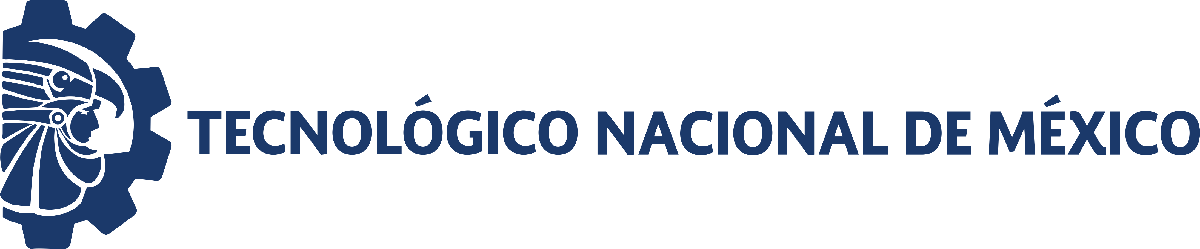                                 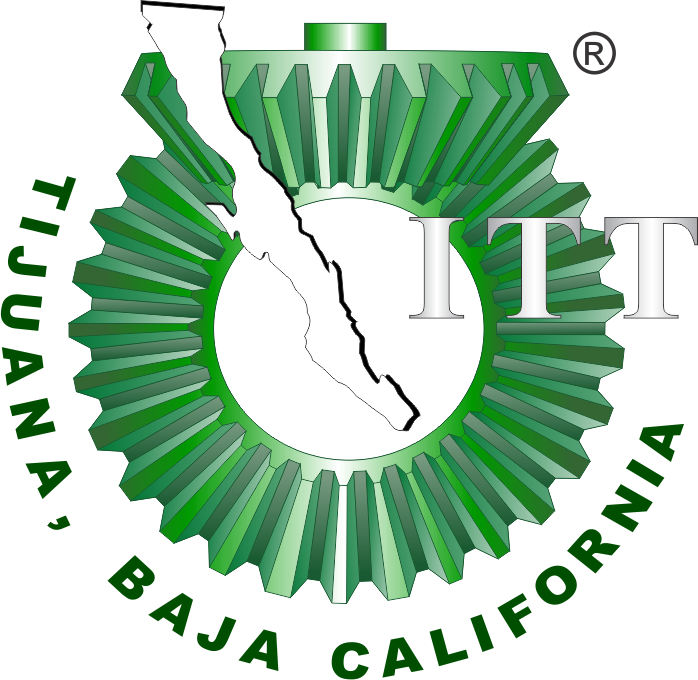

# Práctica 2: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

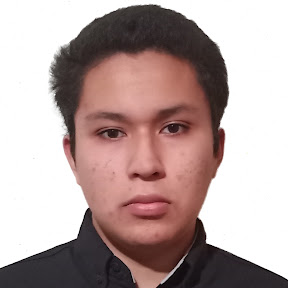

Nombre del alumno: **Ramírez Zepeda Alejandro**

Número de control: **22211765**

Correo institucional: **L22211765@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema2_1';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Graficas lazos abierto y cerrado

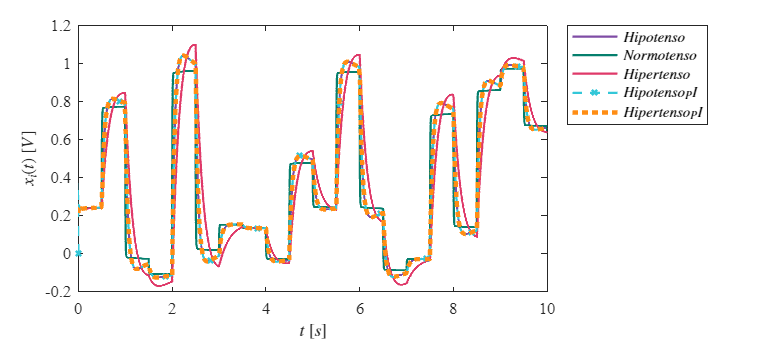

signal1 = 'Graficas lazos abiertos y cerrados';
set_param('Sistema2_1/Ppa(t)','Minimum','-0.2');
set_param('Sistema2_1/Ppa(t)','Maximum','1');
set_param('Sistema2_1/Ppa(t)','Seed','106');
set_param('Sistema2_1/Ppa(t)','SampleTime','0.5');
x = sim(file,parameters);
writematrix(x.Ppa,'signal.xlsx')
plotsignals1(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4,signal1)

## Graficas lazo abierto

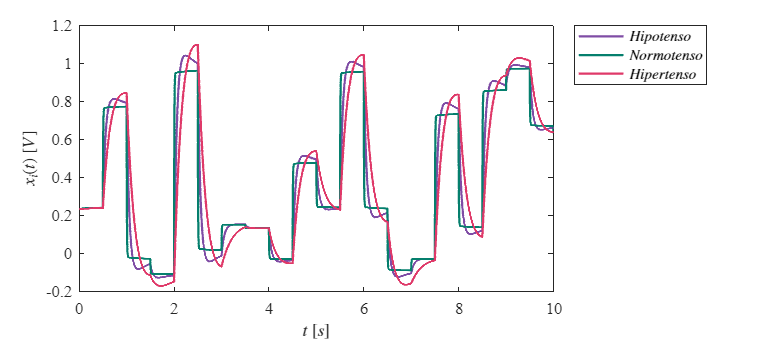

signal2 = 'Graficas lazos abiertos';
set_param('Sistema2_1/Ppa(t)','Minimum','-0.2');
set_param('Sistema2_1/Ppa(t)','Maximum','1');
set_param('Sistema2_1/Ppa(t)','Seed','106');
set_param('Sistema2_1/Ppa(t)','SampleTime','0.5');
x1 = sim(file,parameters);
plotsignals2(x1.t,x1.Pp0,x1.Pp1,x1.Pp2,signal2)

## Función: Respuesta a las señales 1

function plotsignals1(t,Pp0,Pp1,Pp2,Pp3,Pp4,signal1)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors =    [127,76,165;
                5,127,109;
                223,57,105;
                51,199,216;
                255,141,20;
                123,45,67]/255;
    colororder(mycolors)

   p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',t,Pp3,'--x',t,Pp4,':',...
       'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
   set(p(5),'LineWidth',3);

    L = legend('$Hipotenso$','$Normotenso$','$Hipertenso$','$Hipotenso_PI$','$Hipertenso_PI$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    exportgraphics(gcf,[signal1, '.pdf'],'ContentType','vector')
    exportgraphics(gcf,[signal1, '.png'],'ContentType','vector')
    
end

## Función: Respuesta a las señales 2

function plotsignals2(t,Pp0,Pp1,Pp2,signal2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [127,76,165;
                5,127,109;
                223,57,105]/255;
    colororder(mycolors)

    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-', ...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));

    L = legend('$Hipotenso$','$Normotenso$','$Hipertenso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    exportgraphics(gcf,[signal2, '.pdf'],'ContentType','vector')
    exportgraphics(gcf,[signal2, '.png'],'ContentType','vector')

end
